# PMSM Drive Unit Thermal Test Bench for Battery Electric Vehicle (BEV)

Copyright 2022 - 2023 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:open('ElectricVehicleDesignOverview.html')).

## **Drive Unit Thermal Testing and Verification**

 Drive unit (DU) thermal management is critical for durability and life estimation. You need to validate your design under various extreme loading conditions. A sound validation of design reduces the risk of failure in the advanced stages of hardware development. You can also use the DU thermal test bench for real life verification and inverter life estimation. To learn how to setup thermal test bench see, [PMSMmotorTestBenchDescription](matlab:open('./PMSMmotorTestBenchDescription.mlx')). 

### Run Drive Unit Thermal Durability Tests

In this example you will learn how to setup a thermal durability test for the drive unit of a battery electric vehicle (BEV). You perform the thermal durability test unit at constant speed and output torque for the drive unit (DU). You conduct the test at various coolant sump temperatures. The drive unit is runs until it reaches the failure point. The drive unit reaches the failure point when one of these events occur. 

-  The winding temperature  reaches the insulation failure temperature 

-  The magnet temperature reaches the demagnetization temperature 

- The IGBT junction temperature reaches the derating temperature

-  The Diode junction temperature reaches the derating temperature 

If no failure occurs, the test stops at 10,000 s. 

In this example you setup the vehicle speed profiles by defining workspace variables `LSHT` and `HSLT` represent the low speed high torque and high speed low torque. The first column of the matrices is time, and the second column is the vehicle speed  in km/h. You must keep the matrics variable names the elements of the string array `testName. `To achive desired motor output torque, adjust the load on the vehicle. The array `sumpTemperature `defines the coolant temperature`.`

The function `PMSMtestBenchDursaRun` runs the drive unit for all the combinations of speeds and temperatures you define. It returns a summary table of test durations for which the drive unit survived the failure.

% Script for running the Automation  
 LSHT = [0 0;1 5; 2 10; 3 15; 4 20; 5 20]; % Variable name must match with elements of array "testName" 
 HSLT = [0 0;2 20;4 30; 6 45; 8 60; 10 75; 12 85; 14 95;16 100; 18 100]; % Variable name must match with elements of array "testName"
 testName = ["LSHT" "HSLT"]; % Low speed high torque and high speed low torque 
 sumpTemperature = [25 50 90]; % Temperature in degrees Celsius 
 DurabilityTestSummary =  PMSMtestBenchDuraRun(sumpTemperature,testName)

DurabilityTestSummary = 3×2 table
                Test Duration(s) LSHT    Test Duration(s) HSLT
                _____________________    _____________________

    298.15 K            199.5                    10000        
    323.15 K            199.5                    10000        
    363.15 K            190.5                    10000        


### Determine Minimum Gear Ratio    

Drive units with fixed gear ratio are usually the most cost effective option for battery electric vehicle. To determine an appropriate fixed gear ratio, run a design of experiment (DoE) which covers a range of gear ratios and test cycle parameters. This example runs the motor thermal test bench for the DoE that is formed by combinations of array elements `gearRatio` and `testCycle. T`he test duration is attached to a test cycle. Therefore the elements of `runTime` are placed in the corresponding order of the elements defined in `testCycle`.

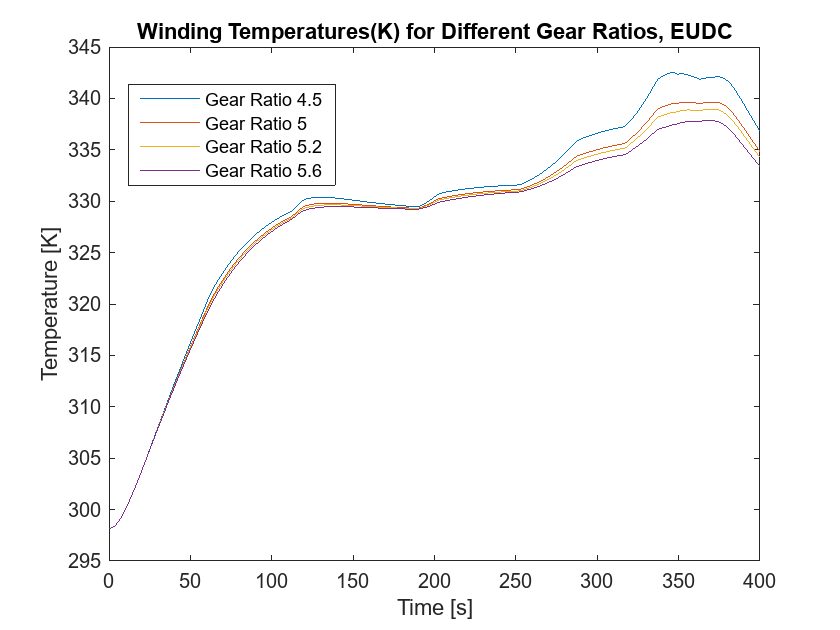

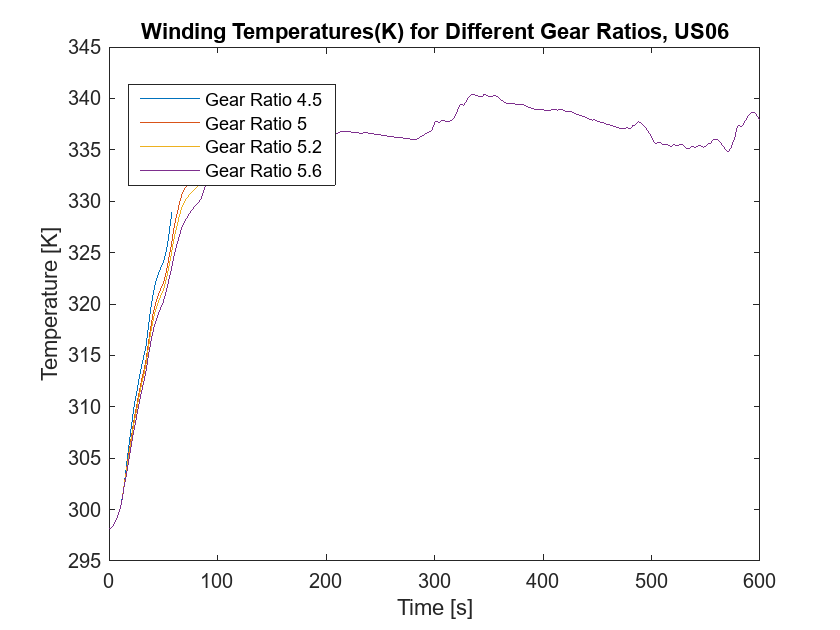

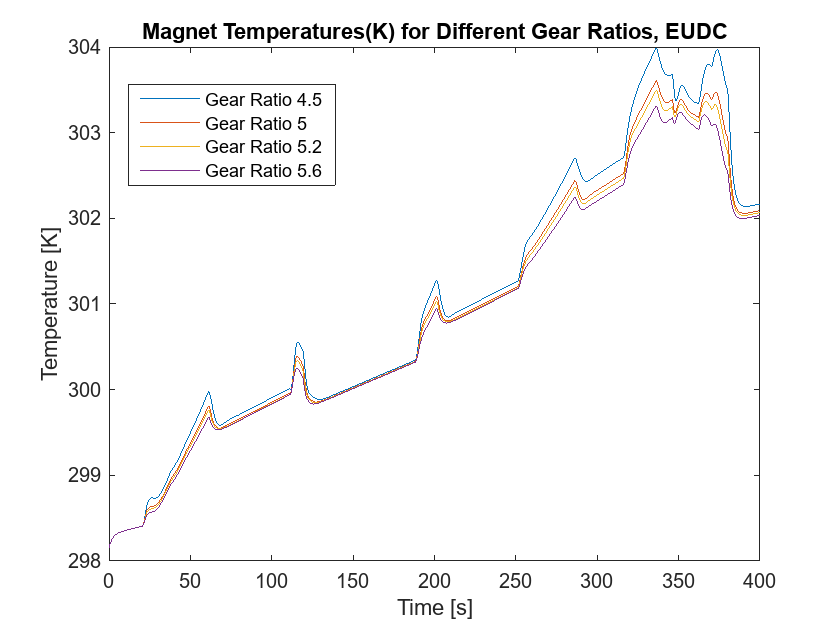

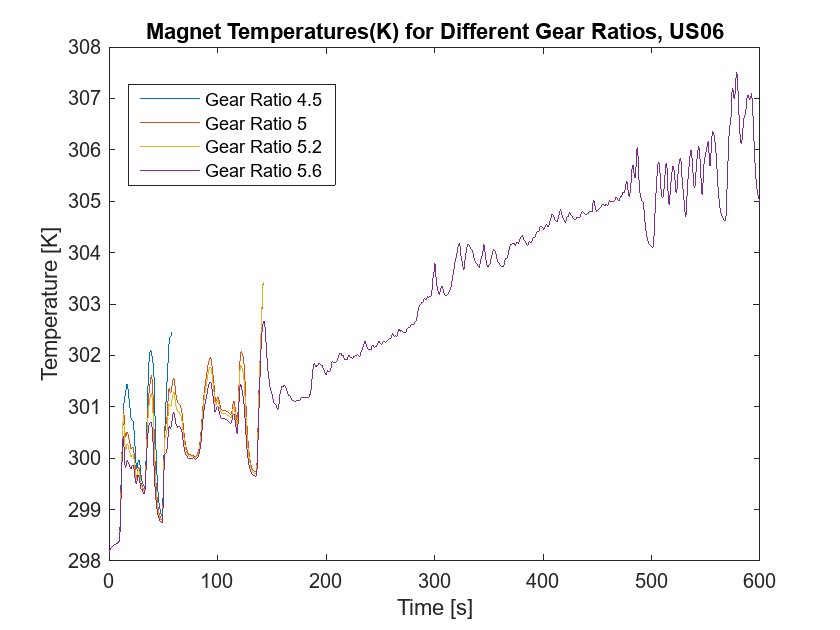

GearRatioDoEsummary = 4×2 table
                       EUDC      US06 
                      ______    ______

    Gear Ratio 4.5    "Pass"    "Fail"
    Gear Ratio 5      "Pass"    "Fail"
    Gear Ratio 5.2    "Pass"    "Fail"
    Gear Ratio 5.6    "Pass"    "Pass"


gearRatio = [4.5,5.0,5.2,5.6];% Gear Ratios 
testCycle = ["EUDC","US06"];% Name of the standard test cycle 
runTime = [400,600];% desired time in sec for which test. (If runTime > standard test time, then the test is repeted for exctra duration)
GearRatioDoEsummary = PMSMtestBenchRun(gearRatio,testCycle,runTime)

Each row of the table `GearRatioDoEsummary` shows the value of gear ratio and if they pass or fail in the test (failure criterion remains same as discussed in previous section). Temperature timeseries output of the simulations is stored in the MAT file `PMSMbatchRunTemp`. Function `PMSMplotMotTemperature` plots the magnet and wing temperatures. At around 300 sec, the winding temperature exceeds the threshold value of 473.15 K in the US06 run for all the gear ratios below 5.6.

### Estimate Inverter End Of Life (EOL) for Duty Cycle  

Inverter life depends upon the thermal fatigue of solder joints. Wire bond lift off and increase in thermal resistance (Rth) beyond a threshold value known as degradation limit are the most common thermal fatigue failure modes. Inverter suppliers provide the values for the increase in thermal resistance with power cycling  however these values are provided for a standard test cycle; for example, with the power on for 1 s followed by 1 s cool off. It is difficult to measure the the exact junction temperature variations during the test so these measurements are often unavailable. It is challenging to estimate the inverter life for a real life driving scenario. However, you can estimate the lifetime of an inverter in terms of the number of  vehicle cycles by converting the thermal cycling the converter experiences during a real life vehicle run into an equivalent number of test cycles. Use script to convert the duty cycle temperature variations into equivalent test cycles. The script uses a formula presented by M. Thoben et. al. in conference publication titled "From vehicle drive cycle to reliability testing of Power Modules for hybrid vehicle inverter". The script requires time series data of the junction temperature for test and vehicle duty cycles. You also need to input the peak test current and end of life thermal resistance. testCycleTemp and PMSMinverterTemp store precomputed results of the simulation. Plot the thermal variations of the inverter for a real life duty cycle and the test cycle and compare the junction temperatures. Red circles indicate peaks and yellow stars indicate valleys. `InverterLife` stores the estimated life of the inverter. 

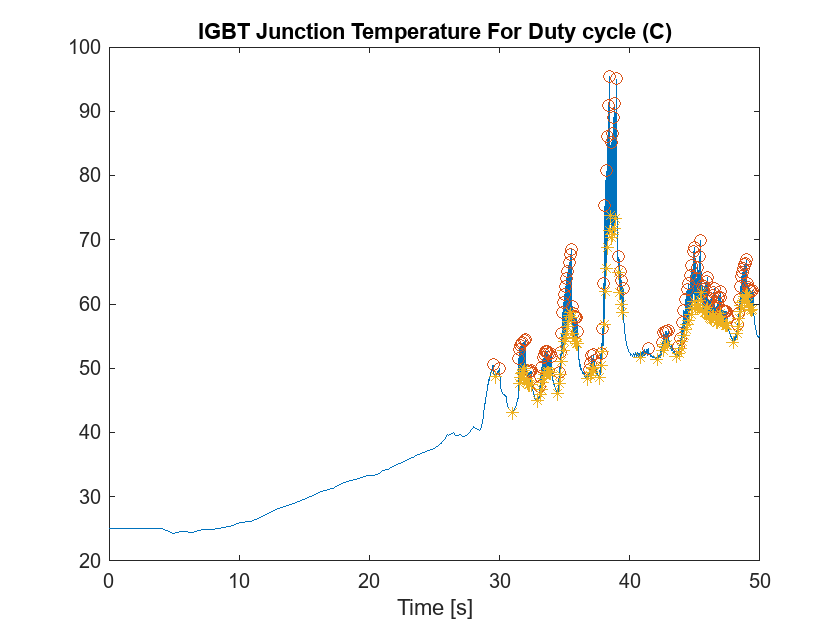

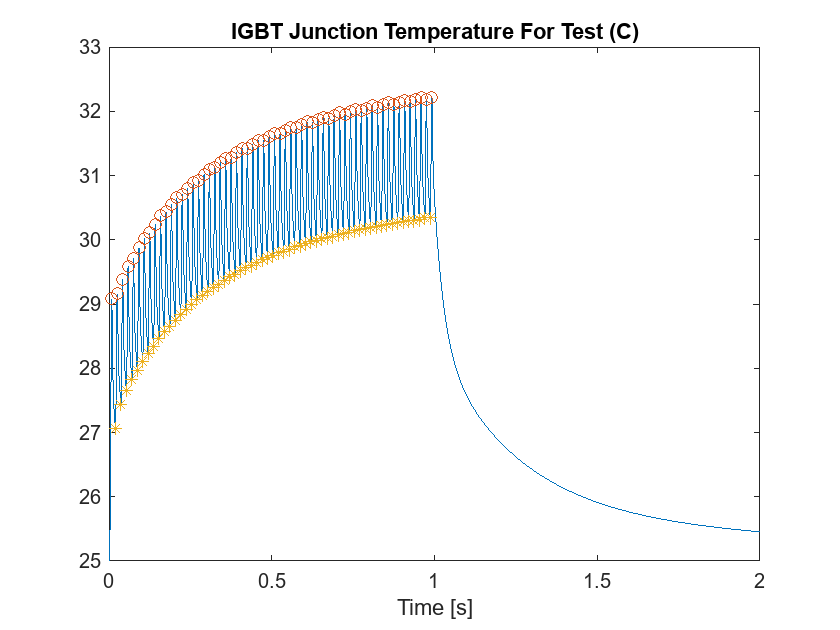

% Script For inverter life estimation
PeakItest = 67.5; %Peak 
EOLrTh = 0.2 ; % end of life thermal resistance (Rth)
TestEqCycles = PMSMcountEqTest(PeakItest);

InverterLife = PMSMgetDutyLife(PeakItest,EOLrTh,TestEqCycles)

InverterLife = 7.4968e+05

dutyCycle = "US06";% Name of the standard test duty cycle 

   To regenerate the time series junction temperature data for a different duty or test cycle, run sample script in the command prompt. 

## **Appendix: Generate Drive Unit Loss Map**

To model a permanent magnet synchronous motor (PMSM) inside a system level thermal simulation, you can generate a motor loss map and integrate it into the system level thermal blocks.

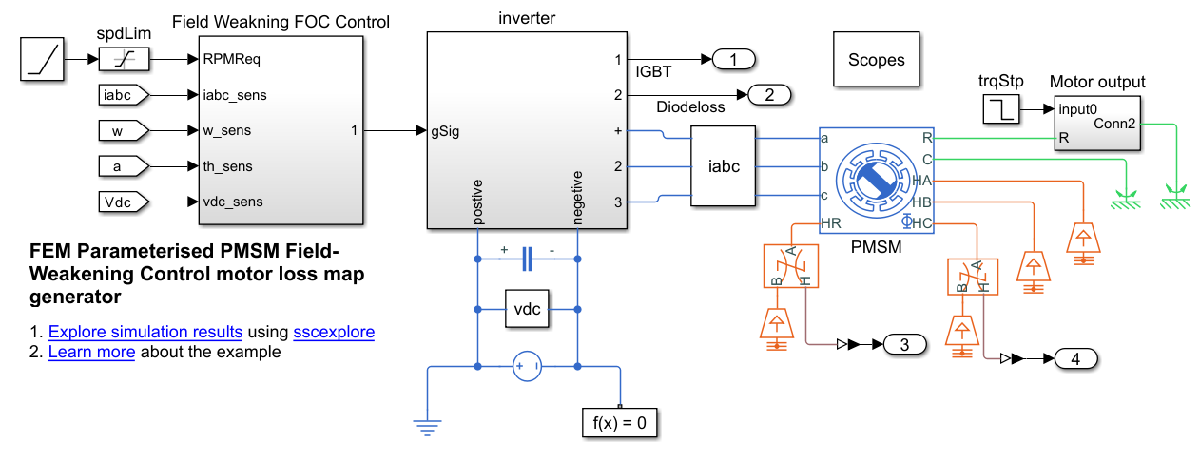

You define the torque speed and inverter junction temperature vectors for the loss map.To generate the motor and inverter loss map, run the `PMSMgetLoss()` function. This function runs the `PMSMfocControlLossMapGen` model for all values of `tqMa`, `tspMat` and `invJnTemp` . To change the parameters of the FEM-Parameterized PMSM in the model, use `PMSMSystemParams`. The function returns a cell array of motor and inverter loss maps. All the three input vectors are reduced to scalars for a quick demostration.

tqMat = [10];% Desired vector of torque Points N-m 
spMat= [500];% Desired vector of speed pionts RPM
invJnTemp = [298.15]; % Desired vector of IGBT and diode junction temperature K
maxMotorPower = 60000.00;% Watts Maximum allowed Motor Power. (Operating points with 
% Torque*Angular velocity above maxMotorPower will not run)
lossMatDU = PMSMgetLoss(tqMat,spMat,invJnTemp,maxMotorPower)

*** Completed Run 1-1


lossMatDU = 1×5 cell array
    {[11.7293]}    {[10]}    {[500]}    {[7.1549]}    {[0.2449]}


In this example, `PMSMmotorLossMap `and `PMSMinverterLossMap` store precomputed loss maps. Supply additional arguments 'overWriteMotLossMap' or 'overWriteInvLossMap' to the function `PMSMgetLoss()` inorder to replace the precomputed loss maps. Use this example code to replace the precomputed loss map :

## Useful Links

[Electric Vehicle Design with Simscape](matlab:open('ElectricVehicleDesignOverview.html'))

[PMSM motor TestBench Description](matlab:open('PMSMmotorTestBenchDescription.mlx'))